% syms s t;
s = tf('s');

student_num = [3 8 1 1 3 5 4 4];
sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

J1 = (student_num(6)+10); % (Kgm^2)
J2 = J1;
J3 = (student_num(2)+10);
JM = J3;
K1 = (student_num(4)+10); % (Nm)
K3 = K1;
K2M = (student_num(5)+10);
K23 = K2M;
B1 = (student_num(7)+10); % (Nms)
B2 = (student_num(3)+10);
BM = (student_num(8)+10);
tauM = 3; % (Nm)


vec_x_dot = [1] % t1 t2 t3 tm w1 w2 w3 wM

vec_x_dot = 1


% x_dot = A*x + B*u

C1_A = [0, 0, 0, 0, 1, 0, 0, 0;   % t1
        0, 0, 0, 0, 0, 1, 0, 0;   % t2 
        0, 0, 0, 0, 0, 0, 1, 0;   % t3
        0, 0, 0, 0, 0, 0, 0, 1;   % tM

        -K1/J1, K1/J1, 0, 0, -B1/J1, 0, B1/J1, 0;   % w1
        K1/J2, -(K1+K2M+K23)/J2, K23/J2, K2M/J2, 0, -B2/J2, 0, B2/J2;   % w2
        0, K23/J3, (-K23-K3)/J3, 0, B1/J3, 0, -B1/J3, 0;   % w3
        0, K2M/JM, 0, -K2M/JM, 0, B2/JM, 0, (-BM-B2)/JM;]; % wM

vec_x = [1]

vec_x = 1


C2_B = [0, 0, 0, 0, 0, 0, 0, 1/JM].'

C2_B =          0
         0
         0
         0
         0
         0
         0
    0.0556



vec_u = [tauM]

vec_u = 3

vec_y_dot = [1] % tK1 tK2M tK23 tK3 tB1 tB2 tBM

vec_y_dot = 1


C3_C = [K1, -K1, 0, 0, 0, 0, 0, 0;     % tK1
         0, K2M, 0, -K2M, 0, 0, 0, 0;   
         0, K23, -K23, 0, 0, 0, 0, 0;
         0, 0, -K3, 0, 0, 0, 0, 0;      % tK3
         0, 0, 0, 0, B1, 0, -B1, 0;        % tB1
         0, 0, 0, 0, 0, B2, 0, -B2;
         0, 0, 0, 0, 0, 0, 0, BM;];

C4_D = [0, 0, 0, 0, 0, 0, 0].';

sys_1 = ss(C1_A, C2_B, C3_C, C4_D)

sys_1 =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1        0        0        0        0        1        0        0        0
   x2        0        0        0        0        0        1        0        0
   x3        0        0        0        0        0        0        1        0
   x4        0        0        0        0        0        0        0        1
   x5  -0.7333   0.7333        0        0  -0.9333        0   0.9333        0
   x6   0.7333   -2.467   0.8667   0.8667        0  -0.7333        0   0.7333
   x7        0   0.7222   -1.333        0   0.7778        0  -0.7778        0
   x8        0   0.7222        0  -0.7222        0   0.6111        0   -1.389
 
  B = 
            u1
   x1        0
   x2        0
   x3        0
   x4        0
   x5        0
   x6        0
   x7        0
   x8  0.05556
 
  C = 
        x1   x2   x3   x4   x5   x6   x7   x8
   y1   11  -11    0    0    0    0    0    0
   y2    0   13    0  -13    0    0 

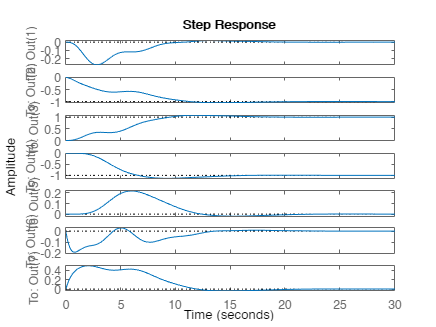


step(sys_1)

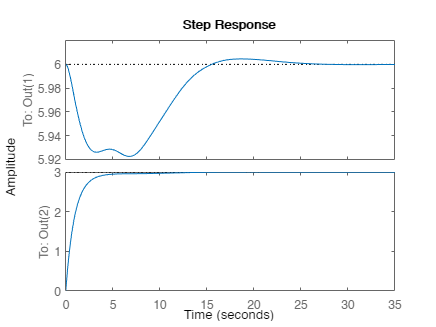

Lw = sn_F/10;
Rw = 2*sn_C/sn_H;
KM = sn_C/sn_H;
Vin = 6;

C5_A = [-Rw/Lw 0      0                0            0       0      0      0      -KM/Lw;
          0      0      0                0            0       1      0      0      0;
          0      0      0                0            0       0      1      0      0;
          0      0      0                0            0       0      0      1      0;
          0      0      0                0            0       0      0      0      1;
          0      -K1/J1 K1/J1            0            0       -B1/J1 0      B1/J1  0;
          0      K1/J2  -(K1+K2M+K23)/J2 K23/J2       K2M/J2  0      -B2/J2 0      B2/J2;
          0      0      K23/J2           -(K3+K23)/J3 0       B1/J3  0      -B1/J3 0;
          KM/JM      0      K2M/JM           0           -K2M/JM  0      B2/JM  0      -(B2+BM)/JM];
C5_B = [Vin/Lw; 0; 0; 0; 0; 0; 0; 0; 0];

C5_C= [0  0 0 0 0 0 0 0 -KM;
          KM 0 0 0 0 0 0 0 0];
C5_D = [Vin; 0];

C5_STM = [s*eye(9)-C5_A]^-1;

sys_2 = ss(C5_A,C5_B,C5_C,C5_D);
step(sys_2)